# Dinámica

clc;
clear all;

## Dinámica de Robots con Ecuaciones de Euler Lagrange

### Teoría

Partimos de la definición del Lagrangiano


$$L=K-V$$


Donde 

$K=\sum_i^n \frac{1}{2}\left(m_i {}^0{\vec{v} }_i\cdot {}^0{\vec{v} }_i+{}^0_0{\vec{\omega} }_i\cdot {}^0J_i\cdot \;{}^0_0{\vec{\omega} }_i\right)$  y $V=\sum_i^n m_i \vec{g} \cdot {}^0{\vec{r} }_i$

Es decir, $K$es la suma de las energías cinética traslacional y rotacional de cada eslabón. Por otro lado, $V$ es la energía potencial de cada eslabón. Cada uno de estos términos de velocidad lineal y angular dependen las posiciones y velocidades del espacio de juntas, es decir, $\vec{\;q} =\left\lbrack q_1 ,q_2 ,{\ldotp \ldotp \ldotp q}_n \right\rbrack$, $\dot{\;\vec{\;q} } =\left\lbrack {\dot{q} }_1 ,{\dot{q} }_2 ,{\ldotp \ldotp \ldotp q}_n \right\rbrack$. 

Recordando que 


$$q_{i\;} =\left\lbrace \begin{array}{ll}
{\theta \;}_i  & \textrm{la}\;\textrm{junta}\;\textrm{es}\;R\\
d_i  & \textrm{la}\;\textrm{junta}\;\textrm{es}\;P
\end{array}\right.$$


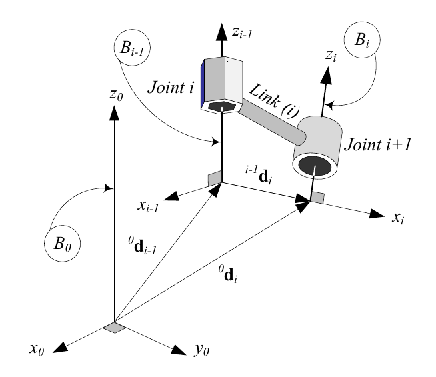

La dependencia respecto al espacio de juntas se puede apreciar si observamos que 


$$\begin{array}{l}
{}^0{\vec{v} }_i={}^0{\dot{\;\vec{d} } }_i=\sum_j^i \left({}^0_0{\vec{\omega} }_j\times {}^0_{j-1}{\vec{d} }_j+\dot{d_j } {}^0{\hat{k} }_{j-1}\right)\;\;\;\;\;\;\;\;\;\;\;\;\dot{d_j } =\left\lbrace \begin{array}{ll}
0 & \textrm{la}\;\textrm{junta}\;\textrm{es}\;R\\
\dot{d_j }  & \textrm{la}\;\textrm{junta}\;\textrm{es}\;P
\end{array}\right.\\
{}^0_0{\vec{\omega} }_i=\sum_j^i {}^0_{j-1}{\vec{\omega} }_j=\sum_j^i \dot{\theta_j } {}^0{\hat{k} }_{j-1}\;\;\;\;\;\;\;\;\;\;\;\;\dot{\theta_j } =\left\lbrace \begin{array}{ll}
\dot{\theta_j }  & \textrm{la}\;\textrm{junta}\;\textrm{es}\;R\\
0 & \textrm{la}\;\textrm{junta}\;\textrm{es}\;P
\end{array}\right.\;\;\;\;\;\;\;\;\;\;\;\;\;\\
{}^0{\hat{k} }_j=\prod_l^j \left({}^{l-1}R_l\left(\theta_l \;\right)\right){}^j{\hat{k} }\;\;\;\;\;\;\;\;\;\;\theta_{l\;} =\left\lbrace \begin{array}{ll}
{\theta \;}_i  & \textrm{la}\;\textrm{junta}\;\textrm{es}\;R\\
0 & \textrm{la}\;\textrm{junta}\;\textrm{es}\;P
\end{array}\right.
\end{array}$$


Por tanto.


$$\begin{array}{l}
{}^0{\vec{v} }_i={}^0{\vec{v} }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n ;{\dot{q} }_1 ,{\dot{q} }_2 \ldotp \ldotp \ldotp {\dot{q} }_n \right)\\
{}^0_0{\vec{\omega} }_i={}^0_0{\vec{\omega} }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n ;{\dot{q} }_1 ,{\dot{q} }_2 \ldotp \ldotp \ldotp {\dot{q} }_n \right)\\
{}^0{\vec{r} }_i={}^0{\vec{r} }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)
\end{array}$$


Entonces


$$L\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n ;{\dot{q} }_1 ,{\dot{q} }_2 \ldotp \ldotp \ldotp {\dot{q} }_n \right)=K\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n ;{\dot{q} }_1 ,{\dot{q} }_2 \ldotp \ldotp \ldotp {\dot{q} }_n \right)-V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)$$


Dado que $K=\sum_i^n \frac{1}{2}\left(m_i {}^0{\vec{v} }_i\cdot {}^0{\vec{v} }_i+{}^0_0{\vec{\omega} }_i\cdot {}^0J_i\cdot \;{}^0_0{\vec{\omega} }_i\right)$ y que se puede relacionar el Jacobiano de desplazamientos ${}^0{\vec{v} }_i=J_{{}^0D_i\;} \dot{\vec{q} }$ y le Jacobiano de rotaciones${}^0_0{\vec{\omega} }_i=J_{{}^0R_i\;} \dot{\vec{q} }$, donde 


$$J_{{}^0D_i\;} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)=\frac{\partial }{\partial \vec{q} }\left({}^0{\vec{r} }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial q_1 }\left({}^0{\vec{r} }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)\\
\frac{\partial }{\partial q_2 }\left({}^0{\vec{r} }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)\\
\vdots \\
\frac{\partial }{\partial q_n }\left({}^0{\vec{r} }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)
\end{array}\right\rbrack$$


y


$$J_{{}^0R_i\;} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)=\frac{\partial }{\partial \vec{q} }\left({}^0{\theta }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial q_1 }\left({}^0{\theta }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)\\
\frac{\partial }{\partial q_2 }\left({}^0{\theta }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)\\
\vdots \\
\frac{\partial }{\partial q_n }\left({}^0{\theta }_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)
\end{array}\right\rbrack$$


Además

${\left\lbrack \vec{q} \right\rbrack }_i =q_i$ Vector de coordenadas/desplazamientos generalizad@s

${\left\lbrack \dot{\vec{q} } \right\rbrack }_i ={\dot{q} }_i$ Vector de velocidades generalizadas

Entonces 


$$\begin{array}{l}
K=\sum_i^n \frac{1}{2}\left(m_i {}^0{\vec{v} }_i\cdot {}^0{\vec{v} }_i+{}^0_0{\vec{\omega} }_i\cdot {}^0J_i\cdot \;{}^0_0{\vec{\omega} }_i\right)\\
K=\sum_i^n \frac{1}{2}\left(m_i {\dot{\vec{q} } }^T {J_{{}^0D_i}^T }_{\;} J_{{}^0D_i} {\dot{\vec{q} } } +{\dot{\vec{q} } }^T J_{{}^0R_i}^T {}^0J_iJ_{{}^0R_i} {\dot{\vec{q} } } \right)\\
K=\sum_i^n \frac{1}{2}\left({\dot{\vec{q} } }^T \left({J_{{}^0D_i}^T }_{\;} m_i \;{J_{{}^0D_i} }_{\;} +J_{{}^0R_i}^T {}^0J_iJ_{{}^0R_i}^T \right){\dot{\vec{q} } } \right)\\
K=\frac{1}{2}{\dot{\vec{q} } }^T \left(\sum_i^n \left({J_{{}^0D_i}^T }_{\;} m_i \;{J_{{}^0D_i} }_{\;} +J_{{}^0R_i}^T {}^0J_iJ_{{}^0R_i}^T \right)\right){\dot{\vec{q} } } 
\end{array}$$


Como el tensor de inercia, solo depende de la distribución espacial del cuerpo $i$, entonces


$${}^0J_i={}^0J_i\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)$$


Por tanto el termino en parentesis se puede reescribir como


$$K=\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } }$$


Donde 


$$D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)=\sum_i^n \left({J_{{}^0D_i}^T }_{\;} m_i \;{J_{{}^0D_i} }_{\;} +J_{{}^0R_i}^T {}^0J_iJ_{{}^0R_i}^T \right)$$


$D$ es conocida como la matriz de inercia, está matriz es simétrica ya que es la multiplicación de los jacobianos de desplazamiento por su transpuesto, es decir, ${{J_{{}^0D_i}^T }_{\;} m_i \;{J_{{}^0D_i} }_{\;} ={\left({J_{{}^0D_i}^T }_{\;} m_i \;{J_{{}^0D_i} }_{\;} \right)}^T }_{\;}$; además ${}^0J_i$ también es simétrico, por tanto $J_{{}^0R_i}^T {}^0J_iJ_{{}^0R_i}^T ={\left(J_{{}^0R_i}^T {}^0J_iJ_{{}^0R_i}^T \right)}^T$. 

Con esta definición reescribimos el Lagrangiano como


$$L\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n ;{\dot{q} }_1 ,{\dot{q} }_2 \ldotp \ldotp \ldotp {\dot{q} }_n \right)=K\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n ;{\dot{q} }_1 ,{\dot{q} }_2 \ldotp \ldotp \ldotp {\dot{q} }_n \right)-V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)$$



$$L\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n ;{\dot{q} }_1 ,{\dot{q} }_2 \ldotp \ldotp \ldotp {\dot{q} }_n \right)=\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } -V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)$$


Se obtiene la ecuación de movimiento mediante Euler-Lagrange


$$\begin{array}{l}
\frac{d}{\textrm{d}t}\left(\frac{\partial }{{\partial \dot{q} }_i }\left(L\right)\right)-\frac{\partial }{\partial q_i }\left(L\right)=Q_i \\
\frac{d}{\textrm{d}t}\left(\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } -V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)\right)-\frac{\partial }{\partial q_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } -V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)=Q_i \\
\frac{d}{\textrm{d}t}\left(\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)\right)-\frac{\partial }{\partial q_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } -V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)=Q_i 
\end{array}$$


Desarrollando el primer término


$$\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)=\frac{1}{2}\frac{\partial }{{\partial \dot{q} }_i }\left({\dot{\vec{q} } }^T \right)D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right){\dot{\vec{q} } } +\frac{1}{2}{\dot{\vec{q} } }^T D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\frac{\partial }{{\partial \dot{q} }_i }\left({\dot{\vec{q} } } \right)$$


Pero $D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)=D^T \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)$, entonces


$$\begin{array}{l}
\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)=\frac{1}{2}\frac{\partial }{{\partial \dot{q} }_i }\left({\dot{\vec{q} } }^T \right)D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right){\dot{\vec{q} } } +\frac{1}{2}{\dot{\vec{q} } }^T D^T \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\frac{\partial }{{\partial \dot{q} }_i }\left({\dot{\vec{q} } } \right)\\
\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)=\frac{1}{2}\frac{\partial }{{\partial \dot{q} }_i }\left({\dot{\vec{q} } }^T \right)D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right){\dot{\vec{q} } } +\frac{1}{2}\frac{\partial }{{\partial \dot{q} }_i }\left({\dot{\vec{q} } }^T \right)D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right){\dot{\vec{q} } } \\
\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)=\frac{\partial }{{\partial \dot{q} }_i }\left({\dot{\vec{q} } }^T \right)D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right){\dot{\vec{q} } } 
\end{array}$$


Además


$$\frac{\partial }{{\partial \dot{q} }_i }\left({\dot{\vec{q} } }^T \right)=\frac{\partial }{{\partial \dot{q} }_i }\left(\left\lbrack \begin{array}{cccccc}
{\dot{q} }_1  & {\dot{q} }_2  & \ldotp \ldotp \ldotp  & {\dot{q} }_i  & \ldotp \ldotp \ldotp  & {\dot{q} }_n 
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{cccccc}
0 & 0 & \ldotp \ldotp \ldotp  & 1 & \ldotp \ldotp \ldotp  & 0
\end{array}\right\rbrack$$


Por tanto


$$\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)=\left\lbrack \begin{array}{cccccc}
0 & 0 & \ldotp \ldotp \ldotp  & 1 & \ldotp \ldotp \ldotp  & 0
\end{array}\right\rbrack D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right){\dot{\vec{q} } }$$


Entonces solo selecciona el $i$-ésimo renglón. Exprensando la multiplicación de matrices como una suma


$$\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)=\sum_i^n \sum_j^n \left(\left\lbrack \begin{array}{cccccc}
0 & 0 & \ldotp \ldotp \ldotp  & 1 & \ldotp \ldotp \ldotp  & 0
\end{array}\right\rbrack D_{i\;j} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right){\dot{q} }_j \right)=\sum_j^n D_{i\;j} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right){\dot{q} }_j$$


El último término es simplemente la matriz e inercia por el vector de velocidad generalizada


$$\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)=\sum_j^n D_{i\;j} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right){\dot{q} }_j ={D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } }$$


Derivando el útimo término respecto al tiempo $t$


$$\frac{d}{\mathrm{d}t}\left(\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)\right)=\frac{d}{\textrm{d}t}\left({D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)={\dot{D} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } +D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\ddot{\vec{q} }$$


Dado que $q_i =q_i \left(t\right)$


$$\dot{D} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)=\left(\sum_k^n \frac{\partial }{\partial q_k }\left(D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right){\dot{q} }_k \right)\dot{\vec{q} }$$


Entonces el primer término se puede reescribir como


$$\begin{array}{l}
\frac{d}{\mathrm{d}t}\left(\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)\right)={\dot{D} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } +D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\ddot{\vec{q} } \\
\frac{d}{\mathrm{d}t}\left(\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)\right)=\left(\sum_k^n \frac{\partial }{\partial q_k }\left(D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right){\dot{q} }_k \right)\dot{\vec{q} } +D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\ddot{\vec{q} } 
\end{array}$$


Expresado la multiplicación de matrices como una suma


$$\frac{d}{\mathrm{d}t}\left(\frac{\partial }{{\partial \dot{q} }_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } \right)\right)=\sum_j^n \left(\left(\sum_k^n \frac{\partial }{\partial q_k }\left(D_{\;i\;j} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right){\dot{q} }_k \right){\dot{q} }_j +D_{i\;j} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\ddot{q_j } \right)$$


El segundo término en la ecuación Euler-Lagrange


$$\frac{\partial }{\partial q_i }\left(\frac{1}{2}{\dot{\vec{q} } }^T {D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\dot{\vec{q} } } -V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)=\frac{1}{2}{\dot{\vec{q} } }^T \frac{\partial }{\partial q_i }\left(D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right){\dot{\vec{q} } } -\frac{\partial }{\partial q_i }\left(V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)$$


Expresando la múltiplicación de matrices como una suma de la expresión anterior


$$\frac{1}{2}{\dot{\vec{q} } }^T \frac{\partial }{\partial q_i }\left(D\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right){\dot{\vec{q} } } =\sum_j^n \left(\sum_k^n \left(\frac{1}{2}\dot{q_k } \frac{\partial }{\partial q_i }\left(D_{k\;j} \left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)\right)\dot{q_j } \right)$$


Entonces

${\left\lbrack H\right\rbrack }_i =H_i =\frac{\partial^2 }{{\partial \dot{q} }_i {\partial q}_j }\left(K\right){\dot{q} }_j -\frac{\partial }{\partial q_i }K\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)$ Vector de acoplamiento

${\left\lbrack G\right\rbrack }_i =G_{i\;} =\frac{\partial }{\partial q_i }V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)$ Vector de fuerzas conservativas generalizadas

${\left\lbrack Q\right\rbrack }_i =Q_i$ Vector de fuerzas generalizadas

Entonces $$


$$\frac{\mathrm{d}}{\mathrm{d}t}\left(\frac{\partial }{\partial {\dot{q} }_i }\left(K\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n ;{\dot{q} }_1 ,{\dot{q} }_2 \ldotp \ldotp \ldotp {\dot{q} }_n \right)-V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)\right)-\frac{\partial }{\partial q_i }\left(K\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n ;{\dot{q} }_1 ,{\dot{q} }_2 \ldotp \ldotp \ldotp {\dot{q} }_n \right)-V\left(q_1 ,q_2 {\ldotp \ldotp \ldotp q}_n \right)\right)=Q_i$$



$$\begin{array}{l}
D\;\ddot{\vec{q} } +H+G=Q\\
D\;\ddot{\vec{q} } +C\dot{\;\vec{\;q} } +\vec{\;G} =\vec{\;Q} 
\end{array}$$


### Código

Para generar el 

clc;
clear all;
syms rho x y z g 'real'             %Sirve para declarar tensor de inercia
r = ([x; y; z]);                    %Vector de posicion respecto al centro de masa
J = ((rho*[r'*r*sym(eye(3)) - r*r']))      %Tensor de inercia respecto al centro de masa

$$J = \left(\begin{array}{ccc} \rho \,\left(y^{2}+z^{2}\right) & -\rho \,x\,y & -\rho \,x\,z\\ -\rho \,x\,y & \rho \,\left(x^{2}+z^{2}\right) & -\rho \,y\,z\\ -\rho \,x\,z & -\rho \,y\,z & \rho \,\left(x^{2}+y^{2}\right) \end{array}\right)$$

g0 = [0; -g; 0]

$$g0 = \left(\begin{array}{c} 0\\ -g\\ 0 \end{array}\right)$$

Parámetro necesarios para el cuerpo 1

syms l_1 h_1 w_1 m_1 'real'
syms theta_1(t)

Obtenemos matriz de tránsformación homegenea del sistema 1 al sistema 0

T0_1 = subs(Ti_j,[a_i, alpha_i, d_i, theta_i],[l_1, 0, 0, theta_1])      % Transformacion Homogenea 0->1

Unrecognized function or variable 'Ti_j'.

Vector de posición del centro de masa del cuerpo 1, expresado en el sistema 0

r0_1 = (0.5*([0; 0; 0; 1] + T0_1(1:4,4)))

Velocidad del centro de masa del cuerpo 1, expresado en el sistema 0

v0_1 = diff(r0_1,t)

Velocidad angular del cuerpo 1, expresado en el sistema 0

omega0_1 = [0; 0; diff(theta_1)]

Tensor de inercia del cuerpo 1

J1_1 = subs(int(int(int(J, x, -l_1/2, l_1/2), y, -h_1/2, h_1/2), z, -w_1/2, w_1/2), [rho], [m_1/(l_1*h_1*w_1)])
J0_1 = (T0_1(1:3,1:3))*J1_1*(T0_1(1:3,1:3)).'

Obtenemos la energía cinética del cuerpo 1

K(1) = simplify(1/2*m_1*(v0_1(1:3)).'*(v0_1(1:3)) + 1/2*omega0_1.'*J0_1*omega0_1) 

Obtenemos energía potencial del cuerpo 1 

V(1) = m_1*g0.'*r0_1(1:3)

Parámatros para el cuerpo 2

syms l_2 h_2 w_2 m_2 'real'
syms theta_2(t)
T1_2 = subs(Ti_j,[a_i, alpha_i, d_i, theta_i],[l_2, 0, 0, theta_2(t)])         % Transformacion Homogenea 1->2
T0_2 = simplify(T0_1*T1_2)
r0_2 = 0.5*(T0_1(1:4,4) +T0_2(1:4,4))
v0_2 = diff(r0_2)
omega0_12 = T0_1(1:3,1:3)*[0; 0; diff(theta_2)]
omega0_2 = omega0_1 + omega0_12

Tensor de inercia del cuerpo 2 expresado en el sistema 0

J2_2 = subs(int(int(int(J, x, -l_2/2, l_2/2), y, -h_2/2, h_2/2), z, -w_2/2, w_2/2), [rho], [m_2/(l_2*h_2*w_2)]);
J0_2 = simplify((T0_2(1:3,1:3))*J2_2*(T0_2(1:3,1:3)).')

Obtenemos la energía cinética del cuerpo 2

K(2) = simplify(1/2*(m_2*v0_2.'*v0_2) + 1/2*omega0_2.'*J0_2*omega0_2)

Obtenemos la energía potencial del cuerpo 2

V(2) = m_2*g0.'*r0_2(1:3)

Entonces el Lagrangiano del sistema será

K = sum(K)
V = sum(V)
L = simplify(sum(K) - sum(V))

Substituimos variables de las juntas por coordenadas generalizadas

syms q_1 q_2 qd_1 qd_2 qdd_1 qdd_2 Q 'real'
q = [q_1; q_2]; qd = [qd_1; qd_2];  qdd = [qdd_1; qdd_2];
K = subs(K, [theta_1, theta_2, diff(theta_1, t), diff(theta_2, t), h_1, h_2], [q_1, q_2, qd_1, qd_2, 0, 0]);
collect(K, qd)
V = subs(V, [theta_1, theta_2], [q_1, q_2])

Obtener la Euler Lagrange

Q = sym(zeros(size(q)));
for i = 1:length(q)
    for j = 1:length(q)
        D(i,j) = diff(diff(K, qd(i)), qd(j));
        C(i,j) = diff(diff(K, qd(i)), q(j));      
    end
    h(i) = diff(K, q(i));
    G(i) = diff(V, q(i));
end
simplify(D)
C
h'
simplify(C*qd - h')
G'
